The Lotka-Volterra Equations for predator-prey with interactions:

Let  $x(t)$ denote the population of the prey species and let$y(t)$denote the population of the predator species.  Then


$$\begin{array}{l}
x^{\prime } =\mathrm{ax}-\alpha \;\mathrm{xy}=f_x \left(x,y\right)\\
y^{\prime } =-\mathrm{cx}+\gamma \;\mathrm{xy}=f_y \left(x,y\right)
\end{array}$$


For positive constants  is the general Lotka-Volterra nonlinear system of differential equations tracking the species over time. Note that in the absence of the predators (when y=0), the prey population would grow exponentially. If the preys are absent (when x=0), the predator population would decay exponentially to zero due to starvation.

Use MATLAB to create a phase-portrait for the Lotka-Volterra system with $a=c=0\ldotp 5$ , and $\alpha =\gamma =0\ldotp 1$.

clear;
% Set up parameters
a =0.5;
c =0.5;
alpha = 0.1;
gamma = 0.2;
rng = linspace(0,10,20);
[xs,ys] = meshgrid(rng);
% We need the f_x, f_y below for Runge-Kutta so do
% the work here. 
fx = @(x,y) a*x - alpha*(x.*y);
fy = @(x,y) -c*y + gamma*(x.*y);
% The vectors (dx, dy)
dxs = fx(xs, ys);
dys = fy(xs, ys);

Get a phase portrait. 

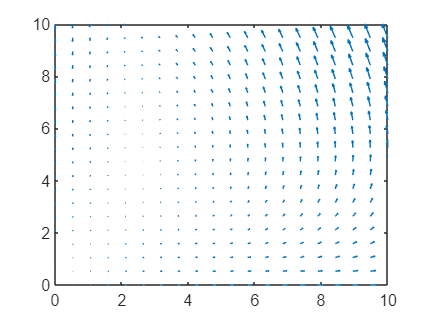

clf;
fig0 = figure();
quiver(xs,ys,dxs,dys)
axes = [0,10,0,10];
xlim([0,10])
ylim([0,10])
hold on

Let's implement 4th order Rung-Kutta by hand. We are given:

$\frac{\mathrm{dy}}{\mathrm{dt}}=f_y \left(x,y\right)$ and $\frac{\mathrm{dx}}{\mathrm{dt}}=f_x \left(x,y\right)$

We start with initial value $x_0$ and $y_0$ and iteravely define 

$y_{i+1} =y_i +\phi_y \left(x_i ,y_i \right)\cdot h$ and $x_{i+1} =x_i +\phi_x \left(x_i ,y_i \right)\cdot h$

Here $h$ is the size of time step that we are using. The $\phi_x$ and $\phi_y$ are defined using $f_x \;$and $f_y$ respectively in the same way, so I describe only $\phi_x$ here. The derivation relies on Taylor series approximations, that we won't do here.


$$\phi_y \left(x_i ,y_i \right)=\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)$$


where


$${\;\;\;\;\;\;\;\;\;\;\;k}_1 =f_y \left(x_i ,y_i \right){\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;k}_2 =f_y \left(x_i +\frac{1}{2}h,y_i +\frac{1}{2}k_1 h\right),$$



$$k_3 =f_y \left(x_i +\frac{1}{2}h,y_i +\frac{1}{2}k_2 h\right)\;{\;\;k}_4 =f_y \left(x_i +h,y_i +k_3 h\right)$$


% This will require a couple more parameters
x0 = 4.2;
y0 = 4.1;
h = 0.3;
stop = 72;
iters = round(stop/h);

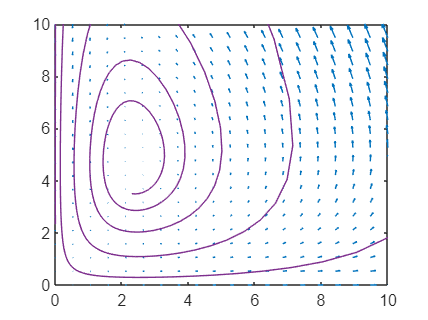

% Define the phi functions
k1 = @(h,x,y,f) f(x,y);
k2 = @(h,x,y,f) f(x + 0.5*h, y + 0.5*h*k1(h,x,y,f));
k3 = @(h,x,y,f) f(x + 0.5*h, y + 0.5*h*k2(h,x,y,f));
k4 = @(h,x,y,f) f(x + h,y + h*k3(h,x,y,f));
phi = @(h,x,y,f) 1/6*(k1(h,x,y,f) + 2*k2(h,x,y,f)...
    + 2*k3(h,x,y,f) + k4(h,x,y,f));
phiy = @(h,x,y) phi(h,x,y,fy);
% To use the same for x I need to swap x and y in sfx 
% and phi 
sfx = @(x,y) fx(y,x);
phix = @(h,x,y) phi(h,y,x,sfx);
xss = ones(iters);
yss = ones(iters);
xss(1) = x0;
yss(1) = y0;
for i = 2:iters
    xss(i) = xss(i-1) + phix(h, xss(i-1), yss(i-1))*h;
    yss(i) = yss(i-1) + phiy(h, xss(i-1), yss(i-1))*h;
end 
plot(xss,yss)
xlim([0,10])
ylim([0,10])